# **K_PhaseHist_demo.mlx**

See also

`K_PhaseHist, K_PhaseHist_test`

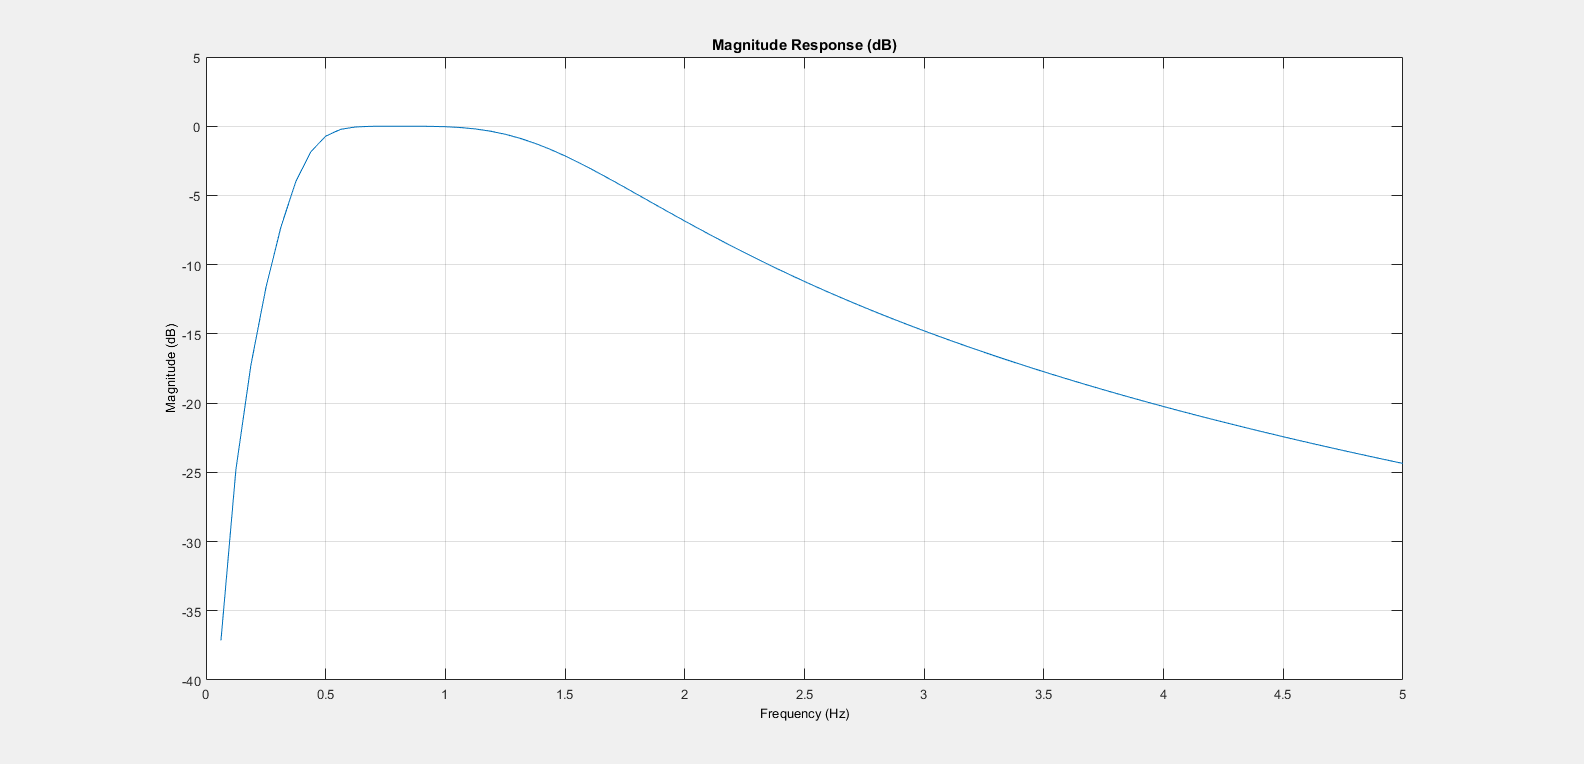

basedir = findbasedir;
if ~isempty(basedir)
    
    testdata1 = fullfile(basedir,...
        'Kouichi MATLAB data','thalamus','S potentials','HF pauser',...
        'PC','SWA','kjx021i01_i02_spliced.mat');
    
    testdata2 = fullfile(basedir,...
        'Kouichi MATLAB data','thalamus','S potentials','HF pauser',...
        'PC','SWA','kjx040e01e02spliced.mat'); 
    
    testdata3 = fullfile(basedir,...
        'Kouichi MATLAB data','thalamus','S potentials','HF pauser',...
        'PC','SWA','kjx019f02@300-828.mat');
    
else
    error('failed to find basedir %s','Private_Dropbox')
end

S1 = load(testdata1);
S2 = load(testdata2);
S3 = load(testdata3);

sRate = 1/S1.unite.interval;
newRate = 1024;

Wn = normalizedfreq([0.4,1.6],newRate);
[b, a] = butter(2, Wn,'bandpass');
fvtool(b,a,'Fs',newRate);
xlim([0 5]);ylim('auto')

assert(isstable(b,a))

# One neuron

Segments: 727, Segment length: 1 sec,  Resolution: 1 Hz.
Segments: 181, Segment length: 4 sec,  Resolution: 0.25 Hz.


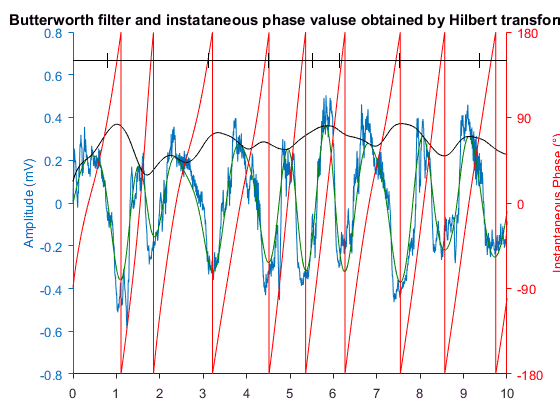

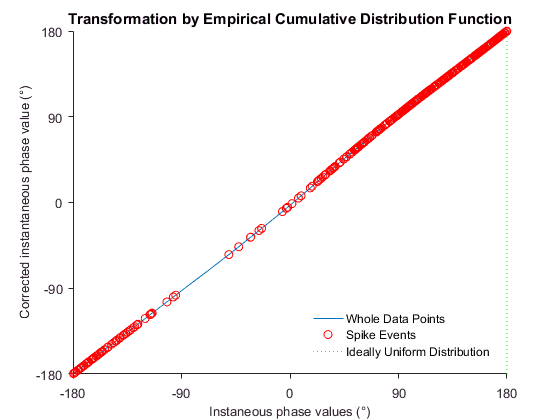

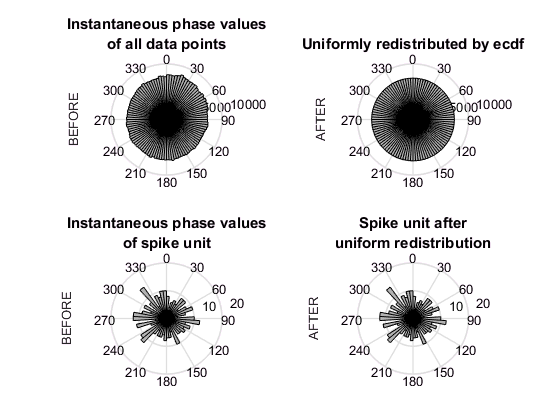

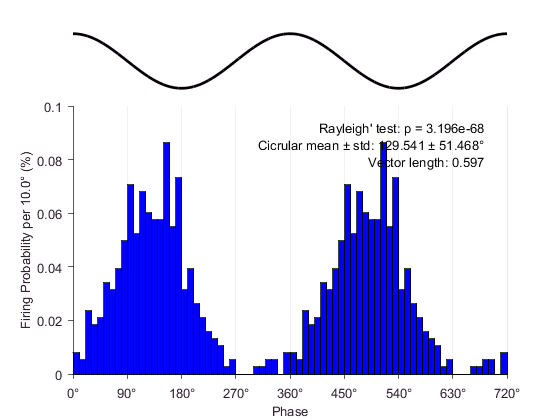

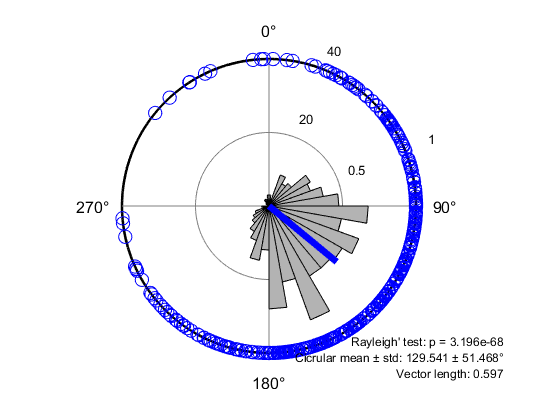

[results,handles] = K_PhaseHist(S1.onset.values, S1.IpsiEEG.values, sRate,...
    newRate, b, a,'plotECDF',true,'PlotLinear',true,'PlotCirc',true);

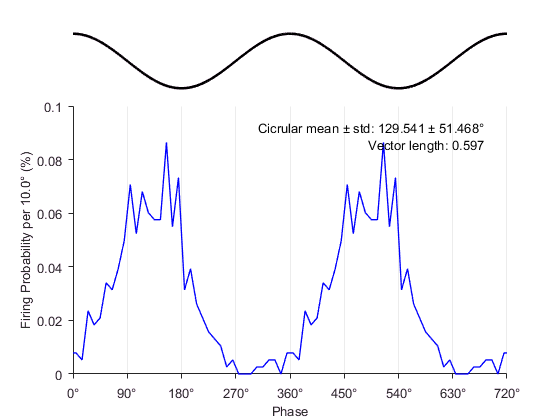

hlin = K_plotLinearPhaseHist(results.unitrad.unitrad);

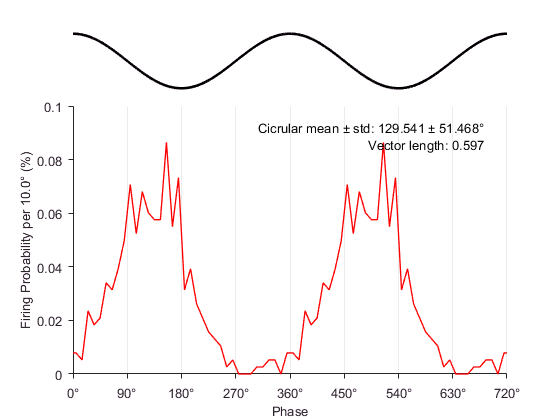


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 'color', 'r',...
    'plottype','line');

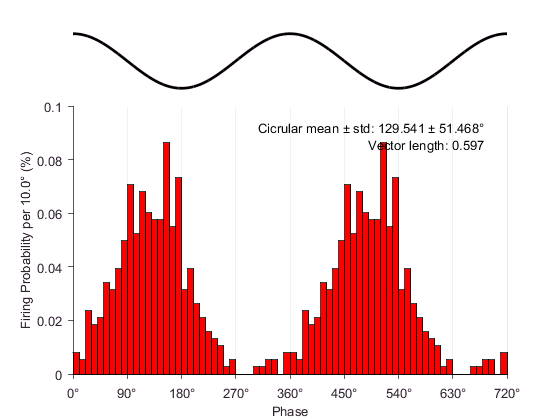


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 'color', 'r',...
    'plottype','bar');


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 'color', 'r',...
    'errorbar','std');% this is not group data so no error bar is shown

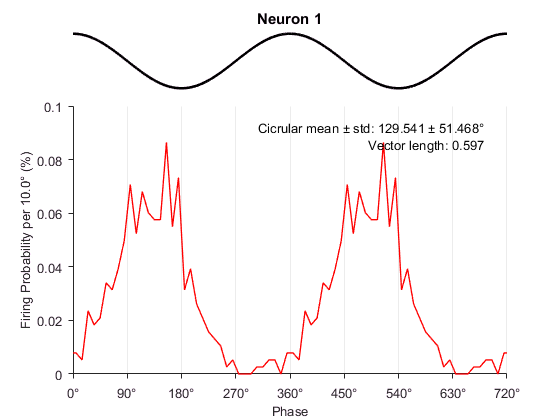


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 'color', 'r',...
    'Title','Neuron 1');

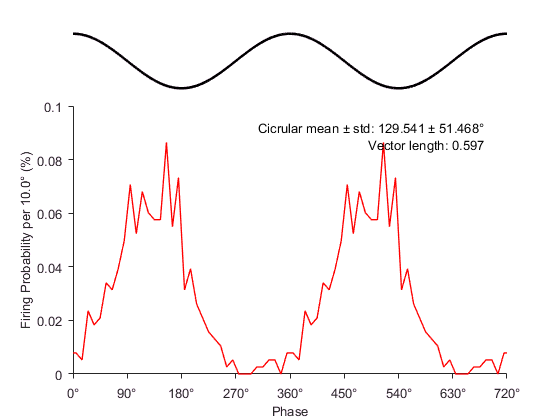


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 'color', 'r',...
    'XGrid','off');

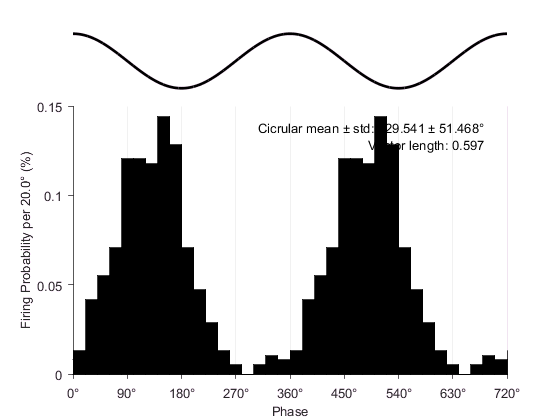


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 18, 'color', 'k',...
    'plottype','bar');

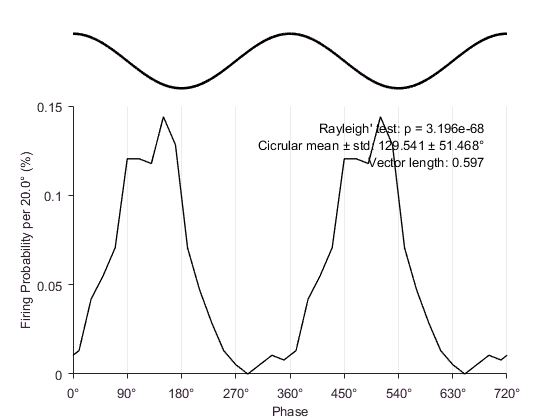


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad, 18, 'color', 'k',...
    'rayleighecdf',results.unitrad.raylecdf);

**plot into an axes**

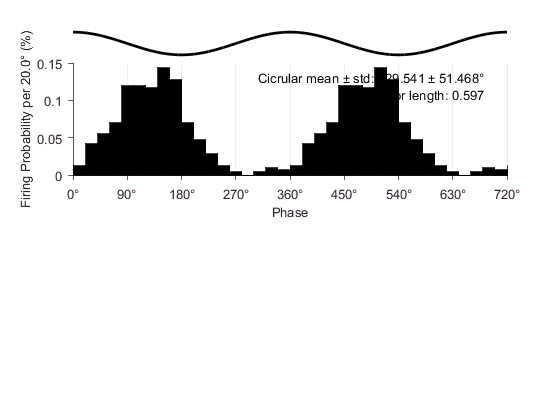

figure;
axh = subplot(2,1,1);
hlin = K_plotLinearPhaseHist(axh,results.unitrad.unitrad, 18, 'color', 'k',...
    'plottype','bar');

**Event with no spike**

results =          unitrad: [1×1 struct]
          eegrad: [1×1 struct]
       eegpwelch: [1×1 struct]
    eegpwelchLow: [1×1 struct]
         ue_lres: [1×1 struct]
         ue_hres: [1×1 struct]


handles =     hunitecdf: []
     heegecdf: []
         hlin: []
        hcirc: [1×1 struct]


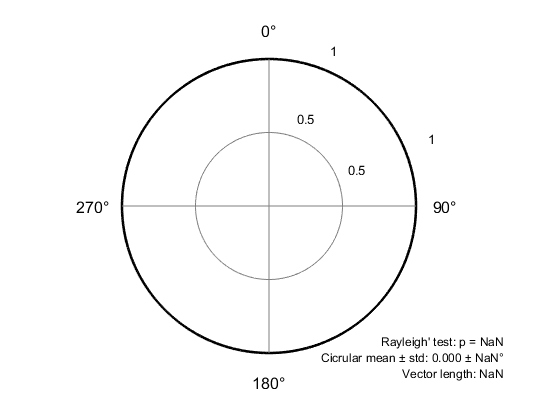

nospk = false(size(S1.onset.values));

[results,handles] = K_PhaseHist(nospk, S1.IpsiEEG.values, sRate,...
    newRate, b, a,'plotECDF',true,'PlotLinear',true,'PlotCirc',true)


hlin = K_plotLinearPhaseHist(results.unitrad.unitrad);

# Group data with K_plotLinearPhaseHist()

results1 = K_PhaseHist(S1.onset.values, S1.IpsiEEG.values, 1/S1.unite.interval, newRate, b, a);

Segments: 727, Segment length: 1 sec,  Resolution: 1 Hz.
Segments: 181, Segment length: 4 sec,  Resolution: 0.25 Hz.


results2 = K_PhaseHist(S2.onset.values, S2.IpsiEEG.values, 1/S2.unite.interval, newRate, b, a);

Segments: 718, Segment length: 1 sec,  Resolution: 1 Hz.
Segments: 179, Segment length: 4 sec,  Resolution: 0.25 Hz.


results3 = K_PhaseHist(S3.onset.values, S3.IpsiEEG.values, 1/S3.unite.interval, newRate, b, a);

Segments: 528, Segment length: 1 sec,  Resolution: 1 Hz.
Segments: 132, Segment length: 4 sec,  Resolution: 0.25 Hz.



radians = {results1.unitrad.unitrad,results2.unitrad.unitrad,results3.unitrad.unitrad};

raylecdf = [results1.unitrad.raylecdf,results2.unitrad.raylecdf,results3.unitrad.raylecdf];


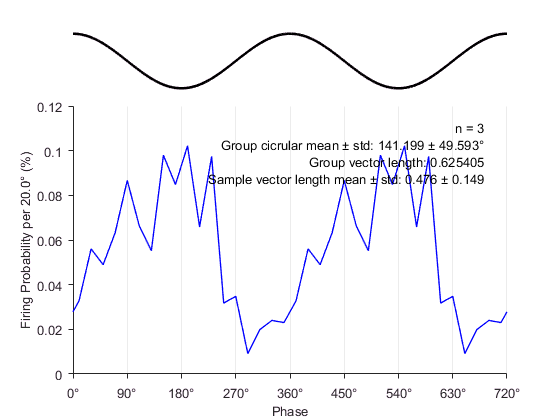

h = K_plotLinearPhaseHist(radians,18); %TODO

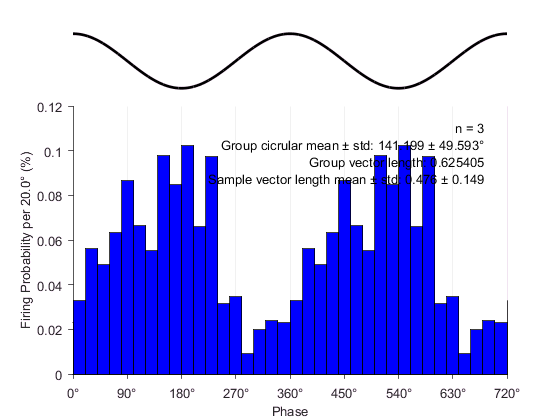


h = K_plotLinearPhaseHist(radians,18,'PlotType','bar');

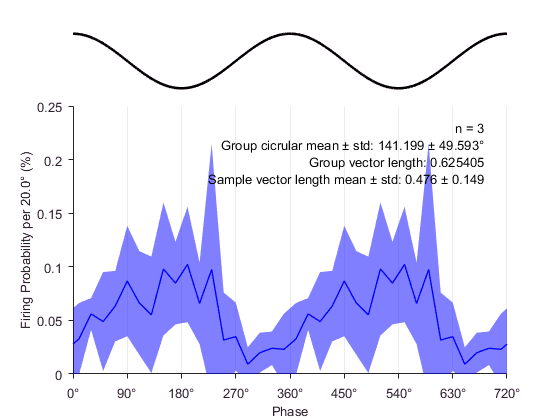


h = K_plotLinearPhaseHist(radians,18,'Errorbar','std');

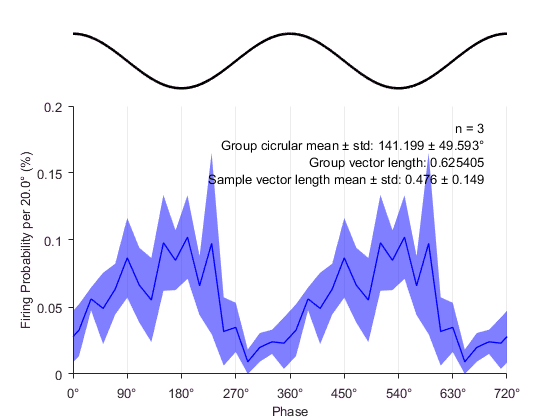


h = K_plotLinearPhaseHist(radians,18,'Errorbar','sem');

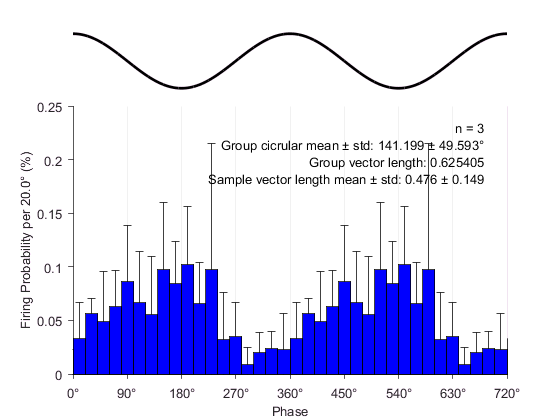


h = K_plotLinearPhaseHist(radians,18,'PlotType','bar','Errorbar','std');

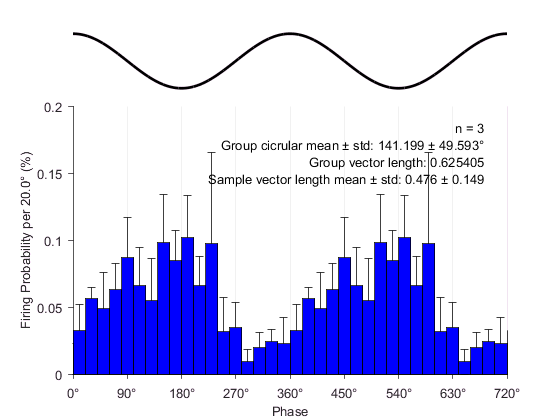


h = K_plotLinearPhaseHist(radians,18,'PlotType','bar','Errorbar','sem');

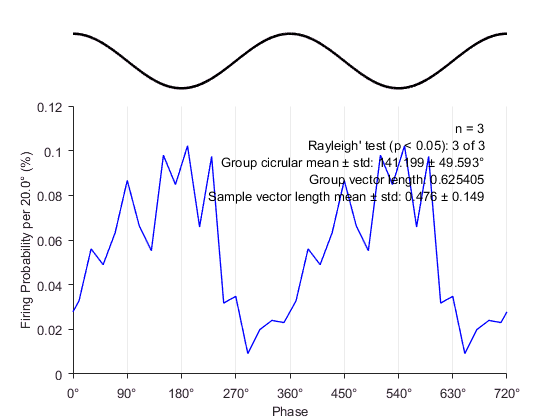


h = K_plotLinearPhaseHist(radians,18,'rayleighecdf',raylecdf);

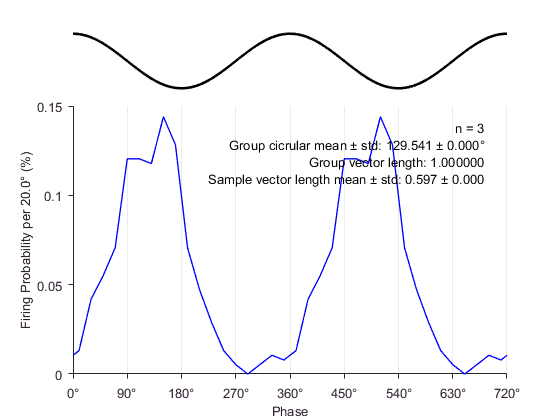




%% Identical three data
radians2 = {results1.unitrad.unitrad,results1.unitrad.unitrad,results1.unitrad.unitrad};

h = K_plotLinearPhaseHist(radians2,18,'Errorbar','std');

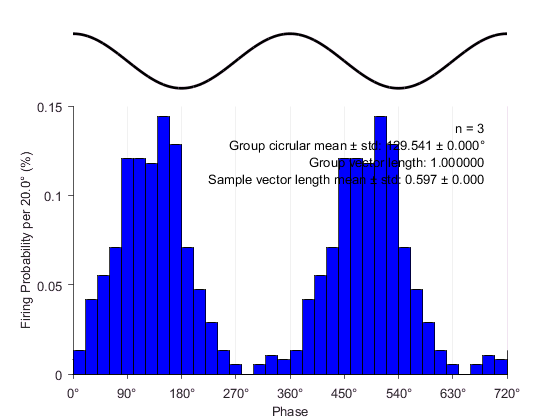


h = K_plotLinearPhaseHist(radians2,18,'PlotType','bar','Errorbar','std');

# K_plotCircPhaseHist_one()

Segments: 727, Segment length: 1 sec,  Resolution: 1 Hz.
Segments: 181, Segment length: 4 sec,  Resolution: 0.25 Hz.



[results,handles] = K_PhaseHist(S1.onset.values, S1.IpsiEEG.values, sRate,...
    newRate, b, a,'plotECDF',true,'PlotLinear',true,'PlotCirc',true);


radians = results.unitrad.unitrad;


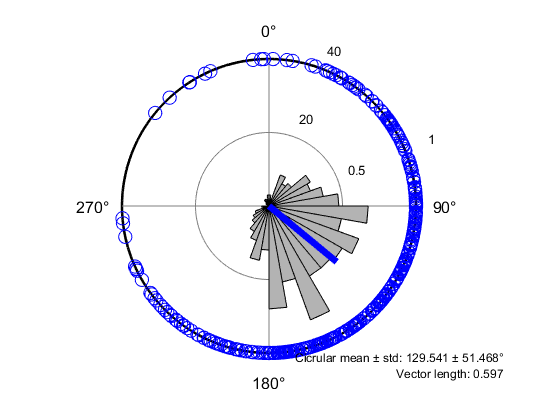

hcirc = K_plotCircPhaseHist_one(radians);

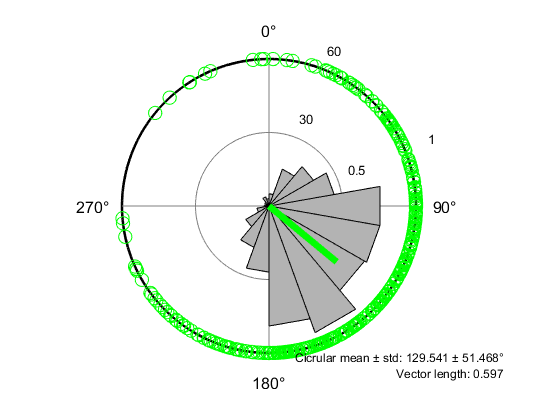


hcirc = K_plotCircPhaseHist_one(radians, 18, 'color', 'g');

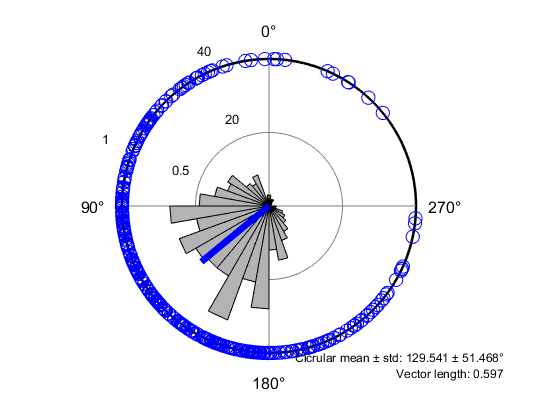


hcirc = K_plotCircPhaseHist_one(radians,'Direction','anti');

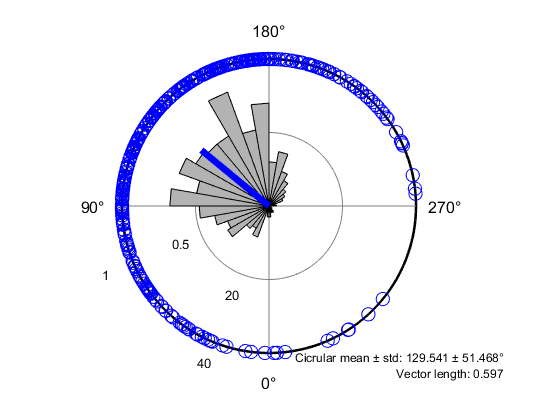


hcirc = K_plotCircPhaseHist_one(radians,'ZeroPos','bottom');

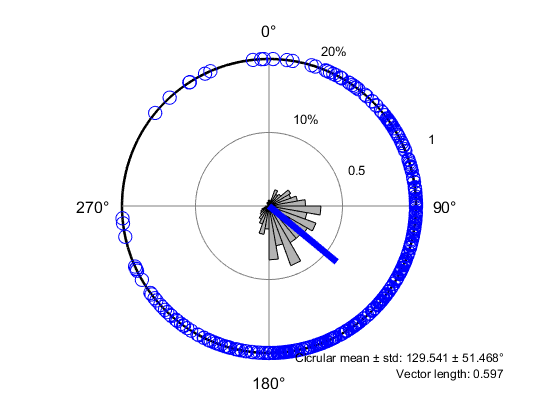


hcirc = K_plotCircPhaseHist_one(radians,'HistLimPercent',20);

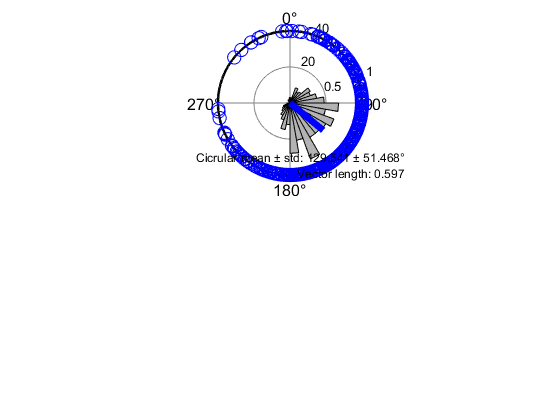


%% axh
figure;
axh = subplot(2,1,1);
hcirc = K_plotCircPhaseHist_one(axh,radians);

# K_plotCircPhaseHist_group()

radians = {results1.unitrad.unitrad,results2.unitrad.unitrad,results3.unitrad.unitrad};

raylecdf = [results1.unitrad.raylecdf,results2.unitrad.raylecdf,results3.unitrad.raylecdf];


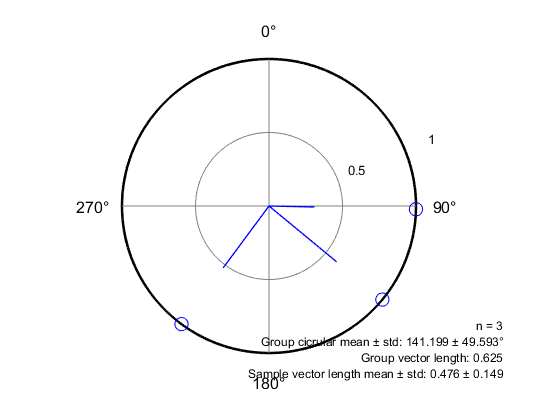

h = K_plotCircPhaseHist_group(radians);

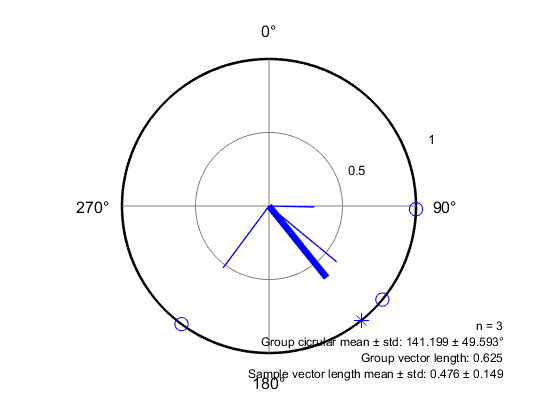


h = K_plotCircPhaseHist_group(radians,'Groupmean','on');

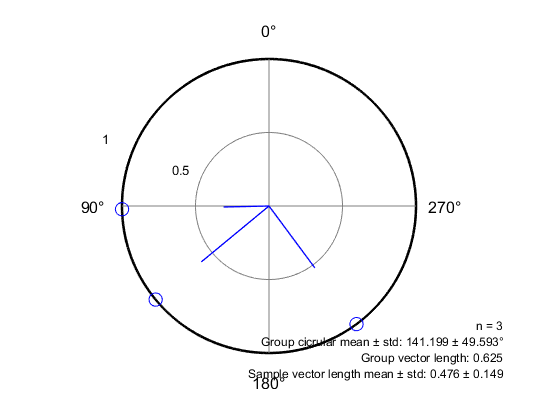


h = K_plotCircPhaseHist_group(radians,'Direction','anti');

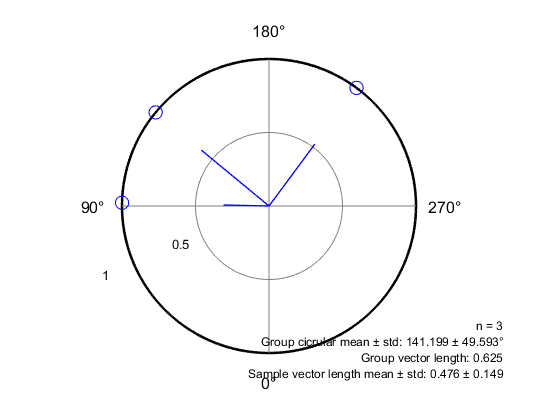


h = K_plotCircPhaseHist_group(radians,'ZeroPos','bottom');

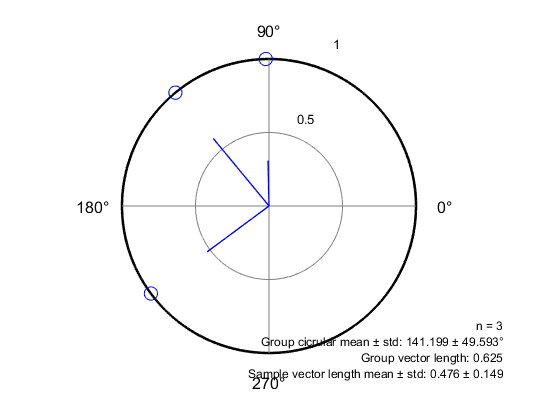


h = K_plotCircPhaseHist_group(radians,'ZeroPos','right','Direction','anti');